# Auto-generated by Data Acquisition Toolbox Analog Input Recorder on 13-Apr-2020 17:19:47

## Create DataAcquisition Object

Create a DataAcquisition object for the specified vendor.

d = daq("directsound");

## Add Channels

Add channels and set channel properties, if any.

addinput(d,"Audio1","1","Audio");

## Read Data

Read the data in timetable format.

DAQ_3 = read(d,seconds(10))

DAQ_3 = 44100×1 timetable
         Time          Audio1_1  
    ______________    ___________

    0 sec              -0.0026855
    2.2676e-05 sec     -0.0023804
    4.5351e-05 sec     -0.0021667
    6.8027e-05 sec     -0.0037537
    9.0703e-05 sec     -0.0037231
    0.00011338 sec     -0.0038147
    0.00013605 sec     -0.0026855
    0.00015873 sec     -0.0016174
    0.00018141 sec    -0.00042725
    0.00020408 sec     -0.0018921
    0.00022676 sec     -0.0016785
    0.00024943 sec     -0.0021667
    0.00027211 sec     -0.0022888
    0.00029478 sec    -0.00097656
    0.00031746 sec    -0.00021362
    0.00034014 sec     0.00018311


## Plot Data

Plot the read data on labeled axes.

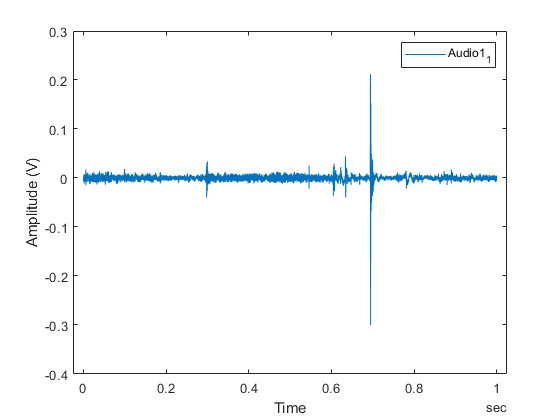

plot(DAQ_3.Time, DAQ_3.Variables)
xlabel("Time")
ylabel("Amplitude (V)")
legend(DAQ_3.Properties.VariableNames)

## Clean Up

Clear all DataAcquisition and channel objects.

clear d